# Part 1

load("Lab2_TXSig.mat");

## (1) Upsampling and Downsampling factors

fs = 5;
fs_TX = 30;
fs_RX = 7.5;
L = fs_TX/fs;
M = fs_RX/fs;
fprintf("upsampling factor L = %.4f", L);

upsampling factor L = 6.0000

fprintf(", downsampling factor M = %.4f\n", M);

, downsampling factor M = 1.5000


## (2) Upsampling (b->c)

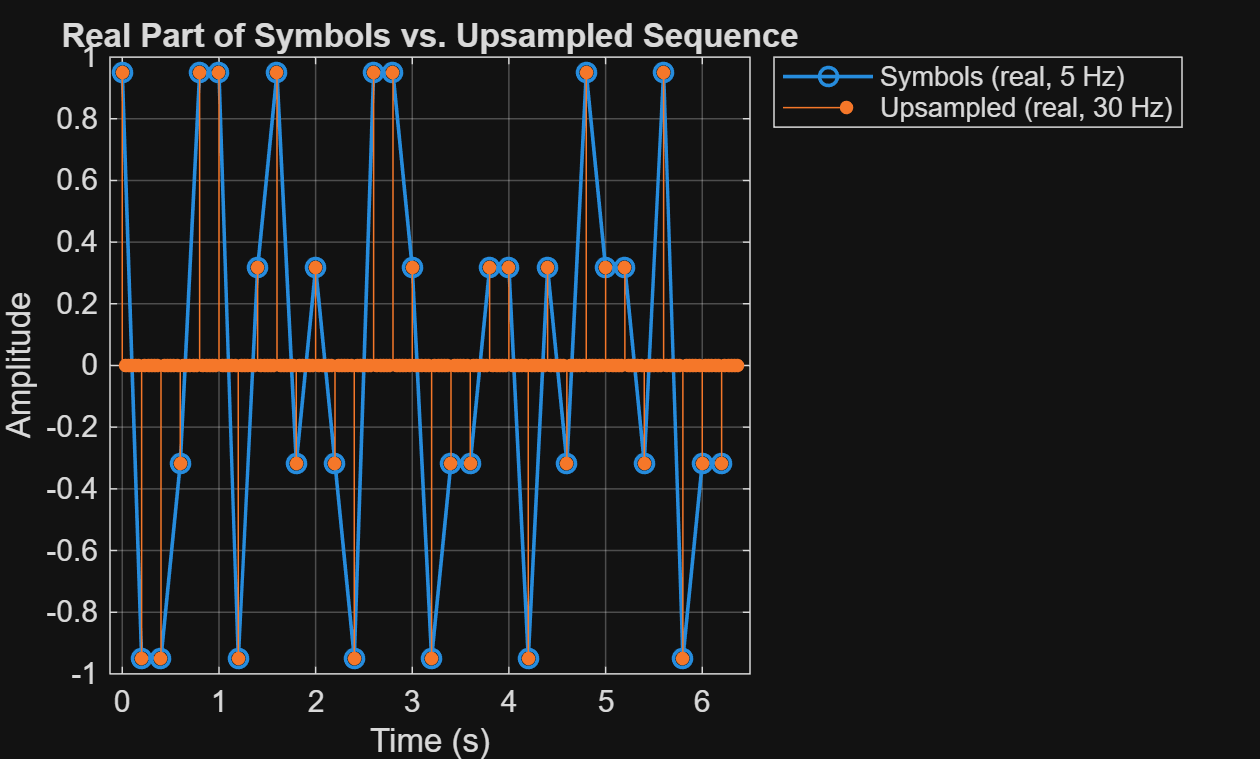

Tdac = 1/fs_TX;   

t_Sym = tSamp(:);

%Upsampling
x_up = upsample(Symbols, L); 
Nup  = length(x_up);
t_up = t_Sym(1) + (0:Nup-1).' * Tdac;

%% Plot real parts on the same figure
figure; 
hold on; grid on; box on;
plot(t_Sym, real(Symbols), 'o-', 'LineWidth', 1.2, 'DisplayName', 'Symbols (real, 5 Hz)');
stem(t_up, real(x_up), 'filled', 'MarkerSize', 4, 'DisplayName', 'Upsampled (real, 30 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of Symbols vs. Upsampled Sequence');
legend('Location', 'northeastoutside'); 



%{
N   = length(Symbols);
Ts  = 1/fs;
Tdac = 1/fs_TX;

t_Sym = tSamp(:);                 % N×1
Symbols = Symbols(:);             % ensure column

%% Linear (averaging) interpolation to DAC rate (30 Hz)
% Produce N*L samples: between each pair of symbols, insert L-1 averaged samples.
x_up = zeros(N*L,1);

for n = 1:N-1
    for i = 0:L-1
        idx   = (n-1)*L + i + 1;
        alpha = i / L;                                % 0, 1/L, ..., (L-1)/L
        x_up(idx) = (1 - alpha)*Symbols(n) + alpha*Symbols(n+1);
    end
end

% Tail: hold the last symbol for the final L samples
x_up((N-1)*L + (1:L)) = Symbols(N);

% Time axis at 30 Hz, aligned to first symbol time
Nup = length(x_up);                                  % = N*L
t_up = t_Sym(1) + (0:Nup-1).' * Tdac;

%% Plot real parts on the same figure
figure; hold on; grid on; box on;

% Original symbols (5 Hz)
plot(t_Sym, real(Symbols), 'o-', ...
    'LineWidth', 1.2, 'MarkerSize', 4, ...
    'DisplayName', 'Symbols (real, 5 Hz)');

% Interpolated to 30 Hz (linear/averaging)
plot(t_up, real(x_up), '-', ...
    'LineWidth', 1.4, ...
    'DisplayName', 'Interpolated (linear, 30 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part: Symbols vs Linear-Interpolated (30 Hz)');
legend('Location','northeastoutside');
%}


## (3) Frequency spectrum of b and c

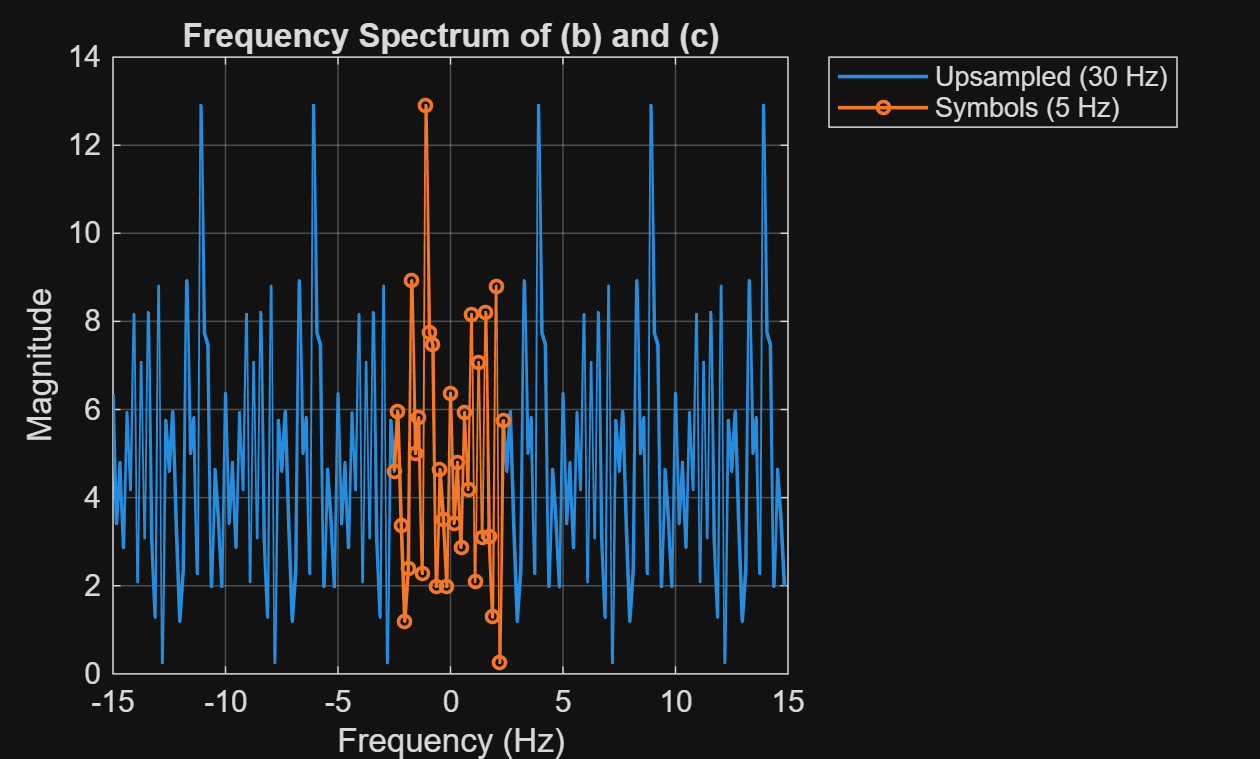

N_sym = length(Symbols);
X_sym = fftshift(fft(Symbols, N_sym));
f_sym = (-N_sym/2:N_sym/2-1) * (fs/N_sym);

N_up = length(x_up);
X_up = fftshift(fft(x_up, N_up));
f_up = (-N_up/2:N_up/2-1) * (fs_TX/N_up);

%% Plot
figure; hold on; grid on; box on;

plot(f_up, abs(X_up), 'LineWidth', 1.2, 'DisplayName', 'Upsampled (30 Hz)');
plot(f_sym, abs(X_sym), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', 'Symbols (5 Hz)');

xlim([-15 15]); 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of (b) and (c)');
legend('Location','northeastoutside');

## (4) Interpolation filter

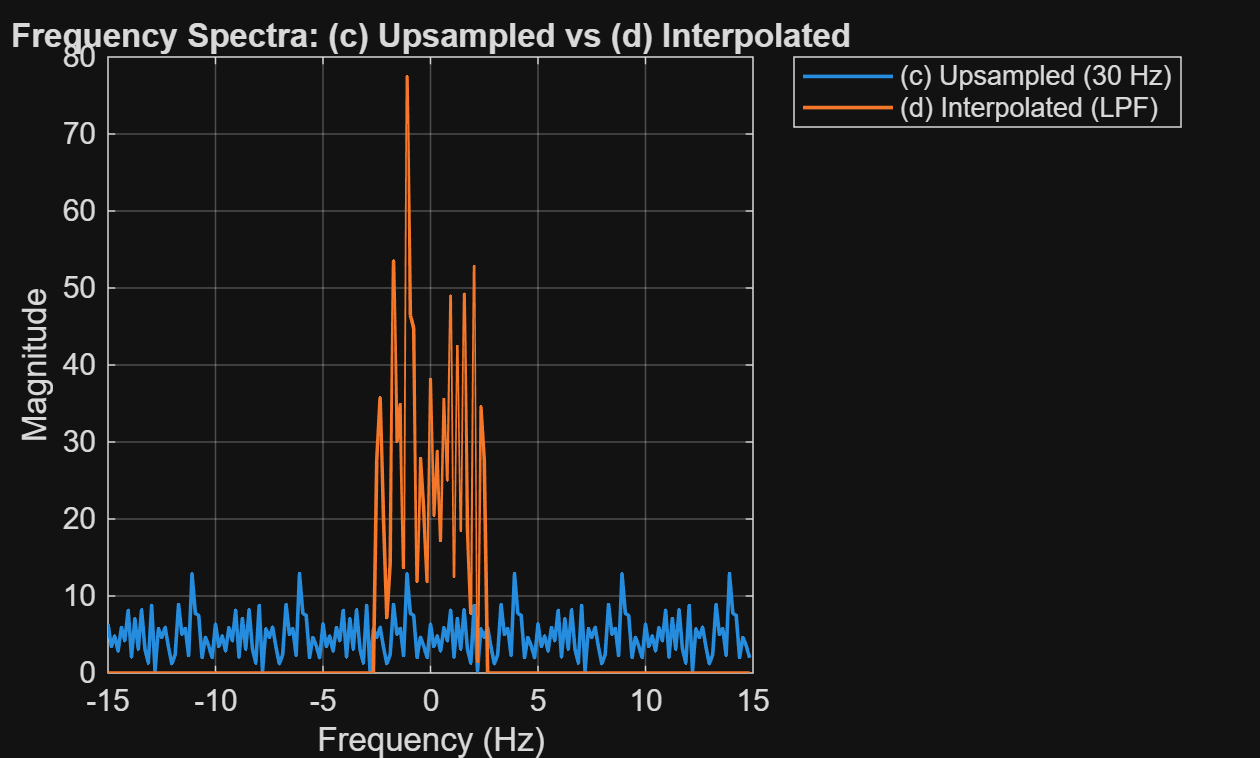

f_cutoff_up = fs/2; 
H  = zeros(size(f_up));
H(abs(f_up) <= f_cutoff_up) = L;

X_up_filtered = X_up .* H.';

figure; hold on; grid on; box on;
plot(f_up, abs(X_up), 'LineWidth', 1.2, 'DisplayName', '(c) Upsampled (30 Hz)');
plot(f_up, abs(X_up_filtered), 'LineWidth', 1.2, 'DisplayName', '(d) Interpolated (LPF)');

xlim([-15 15]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectra: (c) Upsampled vs (d) Interpolated');
legend('Location','northeastoutside');

## (5) Original Symbol vs filtered signal

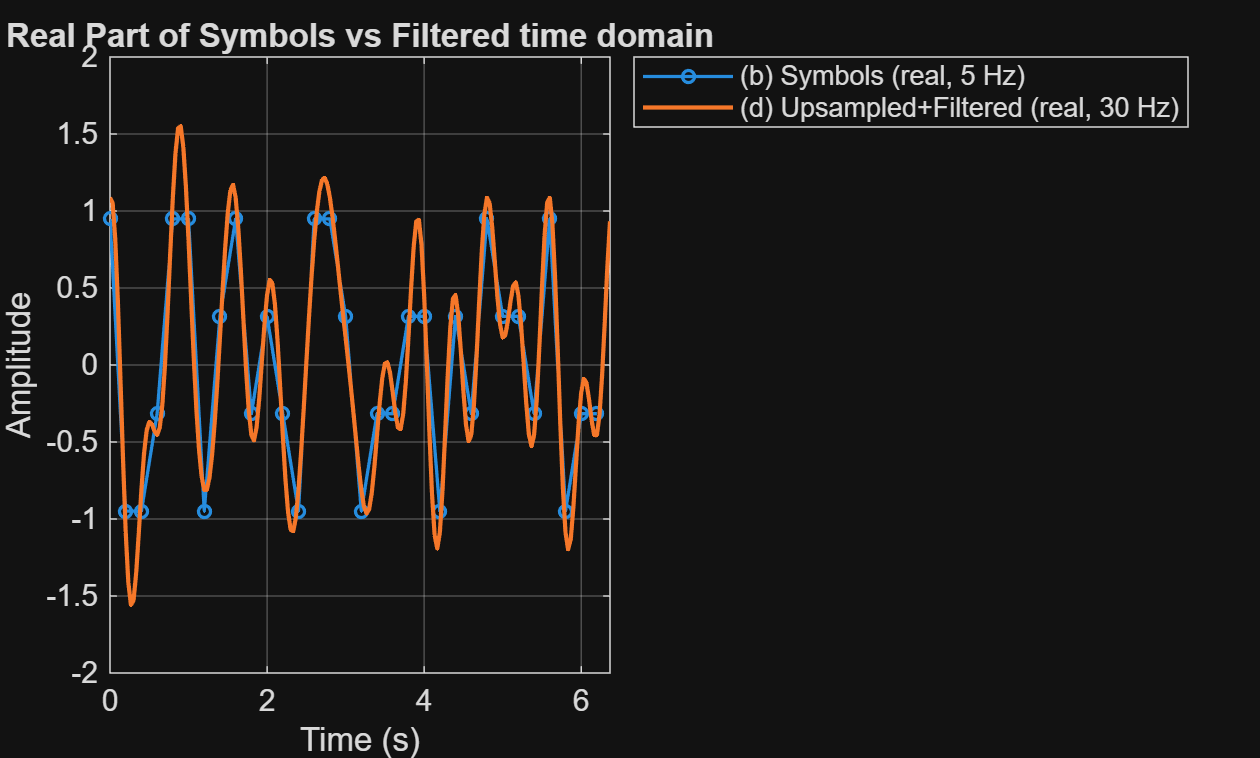

x_up_filtered = ifft(ifftshift(X_up_filtered));

%% Plot real parts of (b) and (d)
figure; hold on; grid on; box on;

%(b)
plot(t_Sym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols (real, 5 Hz)');
%(d)
plot(t_up, real(x_up_filtered), '-', 'LineWidth', 1.4, 'DisplayName', '(d) Upsampled+Filtered (real, 30 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of Symbols vs Filtered time domain');
legend('Location','northeastoutside');

## (6) Signal (e) (After ADC)

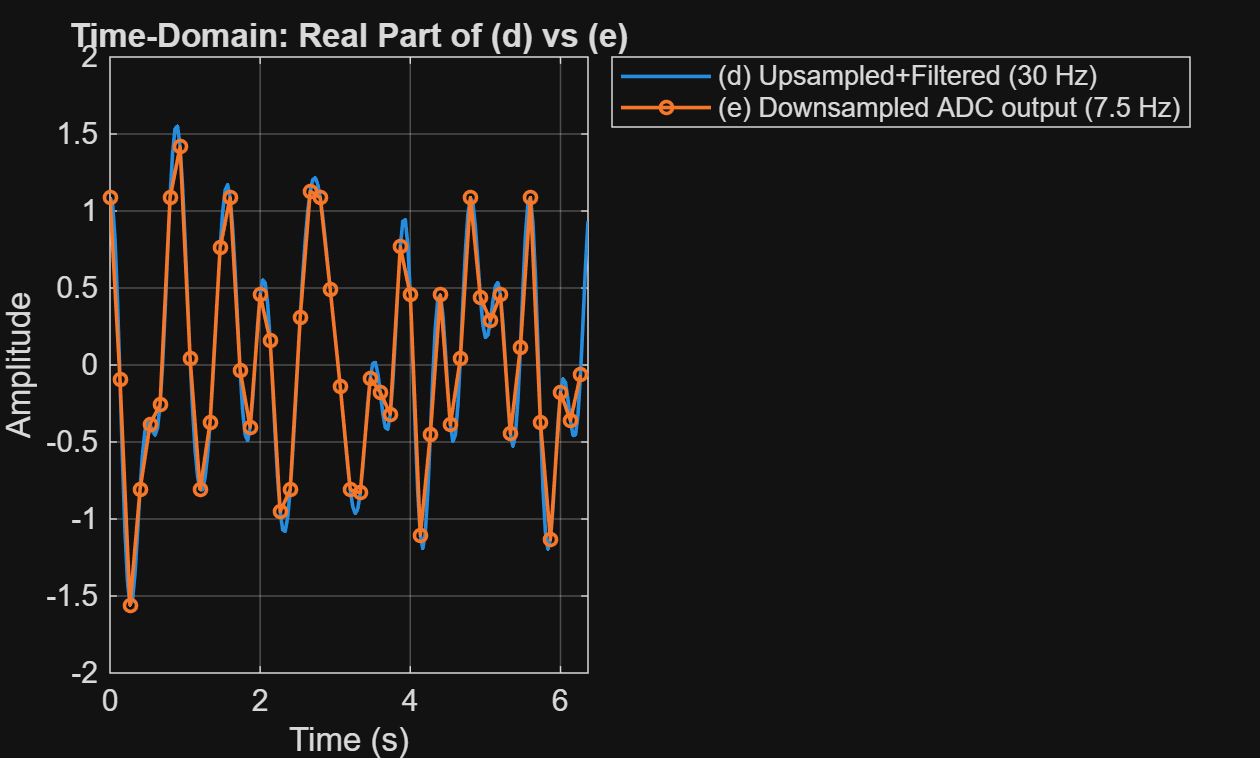

M_de = fs_TX / fs_RX;

x_e   = x_up_filtered(1:M_de:end);
t_e   = t_up(1:M_de:end);

%% Plot real parts of (d) and (e)
figure; hold on; grid on; box on;

%(d)
plot(t_up, real(x_up_filtered), '-', 'LineWidth', 1.2, 'DisplayName', '(d) Upsampled+Filtered (30 Hz)');
%(e)
plot(t_e, real(x_e), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', '(e) Downsampled ADC output (7.5 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Real Part of (d) vs (e)');
legend('Location','northeastoutside');

## (7) upsample by A and downsample by B

M = 1.5 = 3/2

Choose A = 2, B = 3

A = 2;
B = 3;

## (8) Interpolate (e) by A

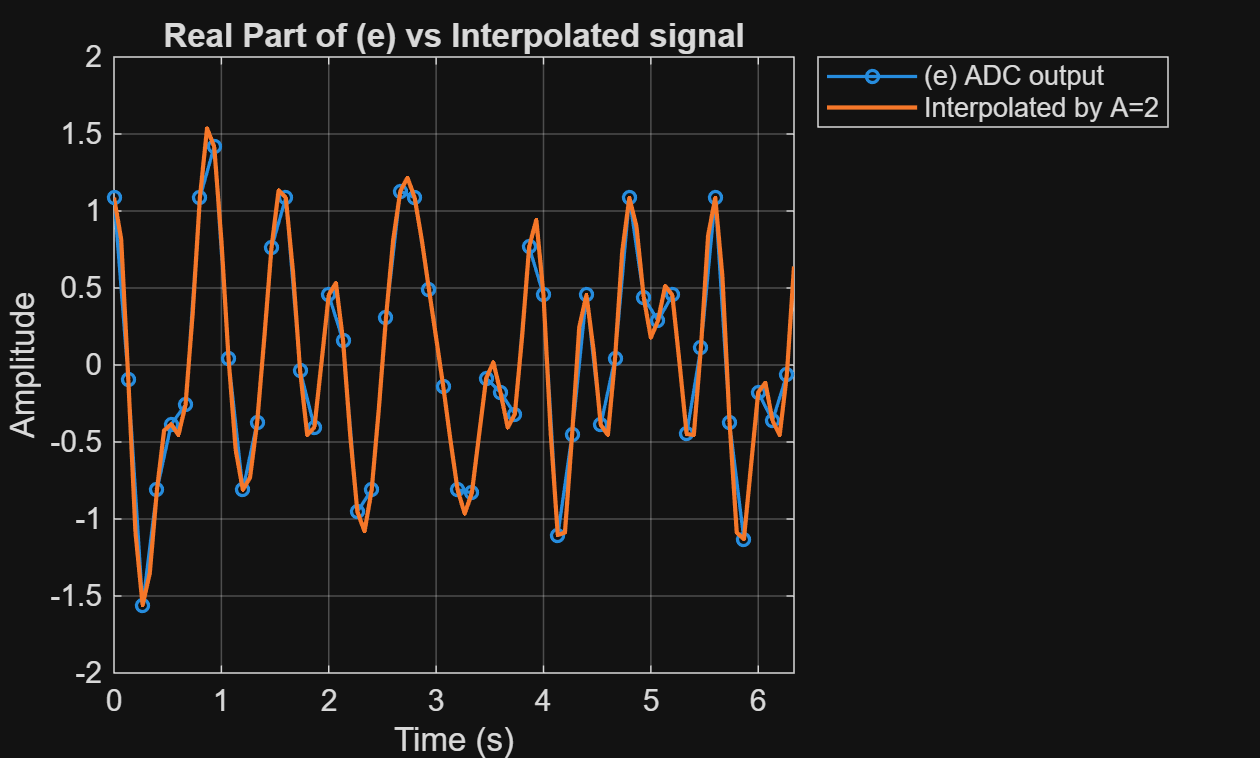

fs_ei = fs_RX * A;      
Tei   = 1/fs_ei;

x_e = x_e(:); 
N   = length(x_e);

x_e_up = upsample(x_e, A);
f_cutoff_e = fs_RX/2;
X_e_up = fftshift(fft(x_e_up, length(x_e_up)));
f_e  = linspace(-fs_RX*A/2, fs_RX*A/2, length(x_e_up));
X_e_up = A*X_e_up .* (abs(f_e) < f_cutoff_e)';
x_e_up = ifft(ifftshift(X_e_up));
               

t_ei = t_e(1) + (0:length(x_e_up)-1).' * Tei;

%% Plot real parts of (e) and the averaged-interpolated signal
figure; hold on; grid on; box on;
plot(t_e,  real(x_e),        'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(e) ADC output');
plot(t_ei, real(x_e_up), '-',  'LineWidth', 1.4, 'DisplayName', 'Interpolated by A=2');
xlabel('Time (s)'); ylabel('Amplitude');
title('Real Part of (e) vs Interpolated signal');
legend('Location','northeastoutside');

## (9) Downsample interpolated (e) by 3

The target frequency is 5Hz, and thus to avoid aliasing, we need LPF from -2.5Hz to 2.5Hz.

Here since we already apply LPF of the same frequency range to obtain (d), we don't need to apply the decimator filter here. 

(we can see from the figure below that frequency of (e) is between -2.5Hz to 2.5 Hz indeed)

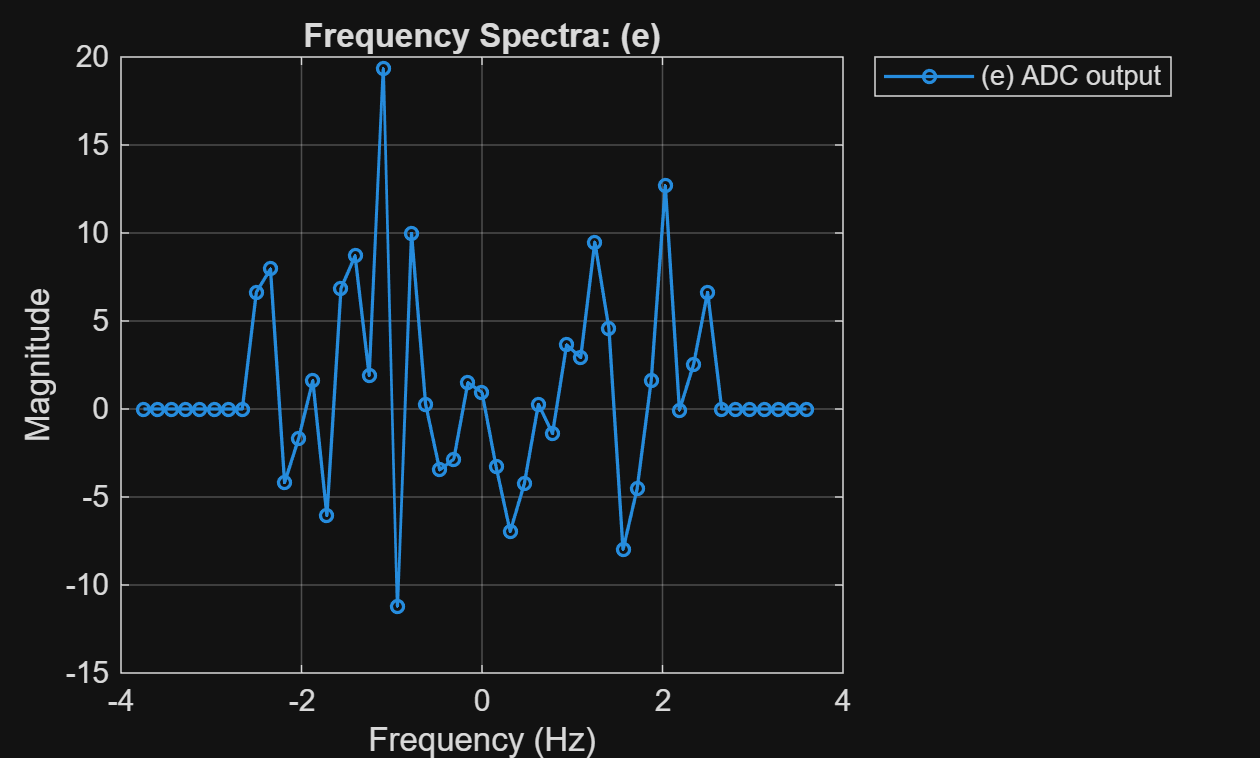

X_e = fftshift(fft(x_e));
f_e = (-length(x_e)/2:length(x_e)/2-1).' * (fs_RX / length(x_e));
figure; hold on; grid on; box on;

% (e) 
plot(f_e, real(X_e), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(e) ADC output');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectra: (e)');
legend('Location','northeastoutside');

## (10) Downsample interpolated (e) by 2

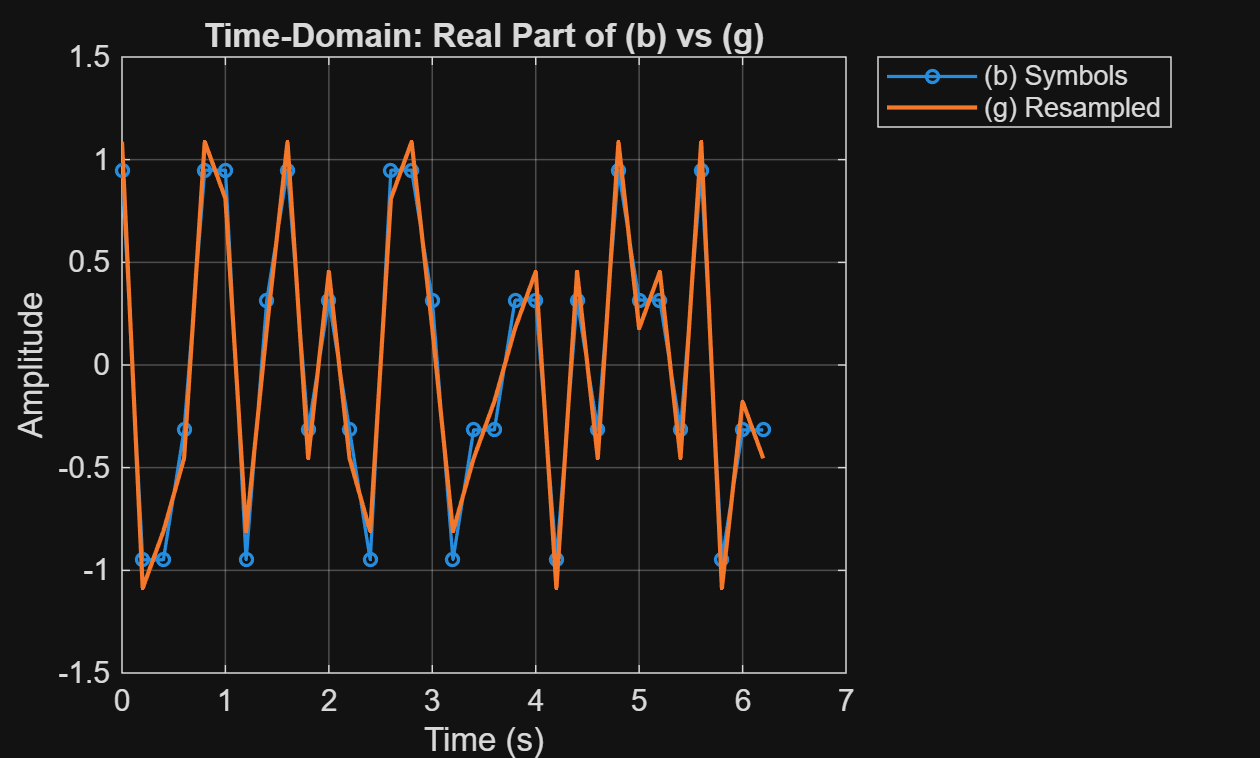

x_g = x_e_up(1:B:end);
t_g   = t_Sym;

%% Plot
figure; hold on; grid on; box on;

% (b)
plot(t_Sym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols');

plot(t_g, real(x_g), '-', 'LineWidth', 1.4, 'DisplayName', '(g) Resampled');

xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Real Part of (b) vs (g)');
legend('Location','northeastoutside');

## (11) Demodulate and check bit error rate

est_bits = qamdemod(x_g, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');

% Count bit errors
num_bit_errors = sum(est_bits(:) ~= bits(:));
ber = num_bit_errors / numel(bits);

fprintf('Bit errors = %d (BER = %.3g)\n', num_bit_errors, ber);

Bit errors = 0 (BER = 0)


# Part 2

## (1) (b) and (d) in time domain

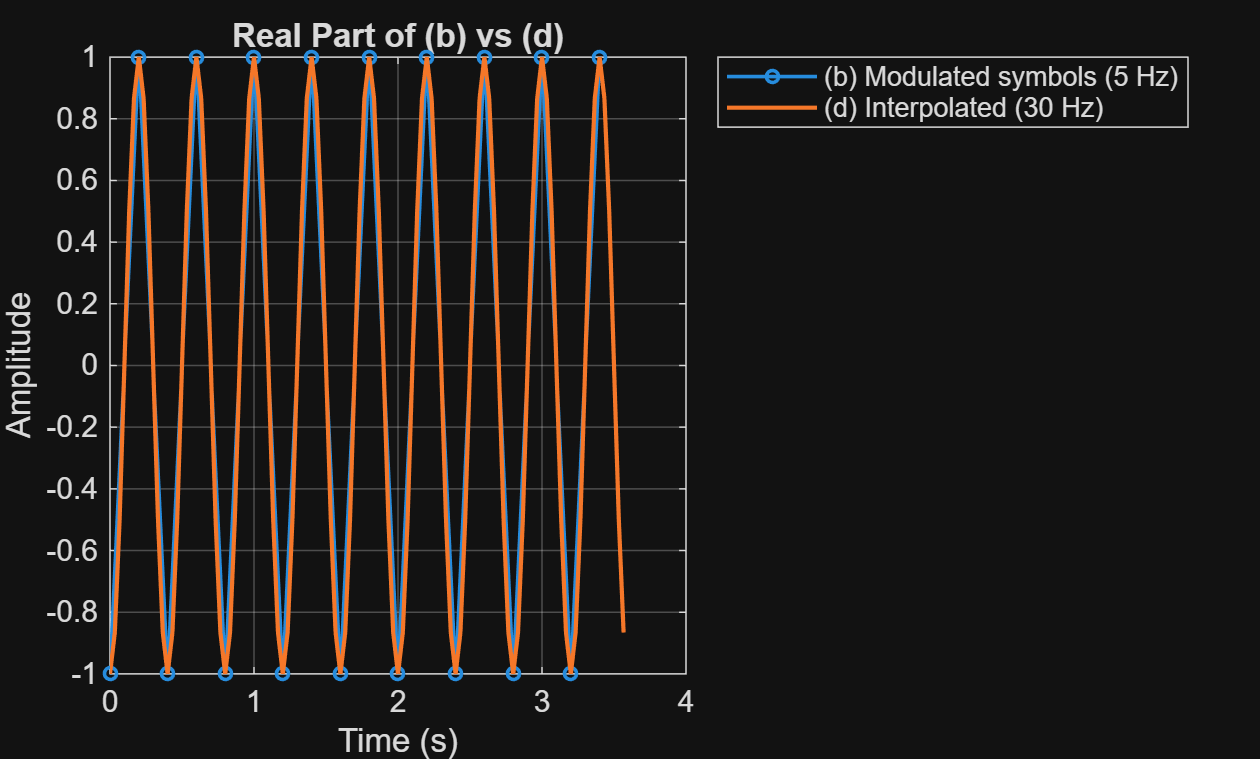

fs_sym = 5;
L      = 6;
fs_up  = fs_sym * L;

bits = [1;0;1;0;1;0;1;0;1;0;1;0;1;0;1;0;1;0];
Nsym = length(bits);

Symbols = 1-2*bits;

tSym = (0:Nsym-1)'/fs_sym;

% Upsampling
x_up = upsample(Symbols,L);
N_up = length(x_up);
t_up = (0:N_up-1)'/fs_up;

X_up = fftshift(fft(x_up,N_up));
f_up = (-N_up/2:N_up/2-1)'*(fs_up/N_up);

f_cutoff = fs_sym/2;
H  = zeros(size(f_up));
mask = (f_up < f_cutoff) & (f_up >= -f_cutoff);
H(mask) = L; 
% H(abs(f_up) <= fc) = L;

X_up_filtered = X_up .* H;
x_d = ifft(ifftshift(X_up_filtered),N_up);

%% Plot real parts of (b) and (d)
figure; hold on; grid on; box on;
plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(b) Modulated symbols (5 Hz)');
plot(t_up,  real(x_d),    '-',  'LineWidth', 1.4, 'DisplayName','(d) Interpolated (30 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b) vs (d)');
legend('Location','northeastoutside');

## (2) (b) and (d) in frequency domain

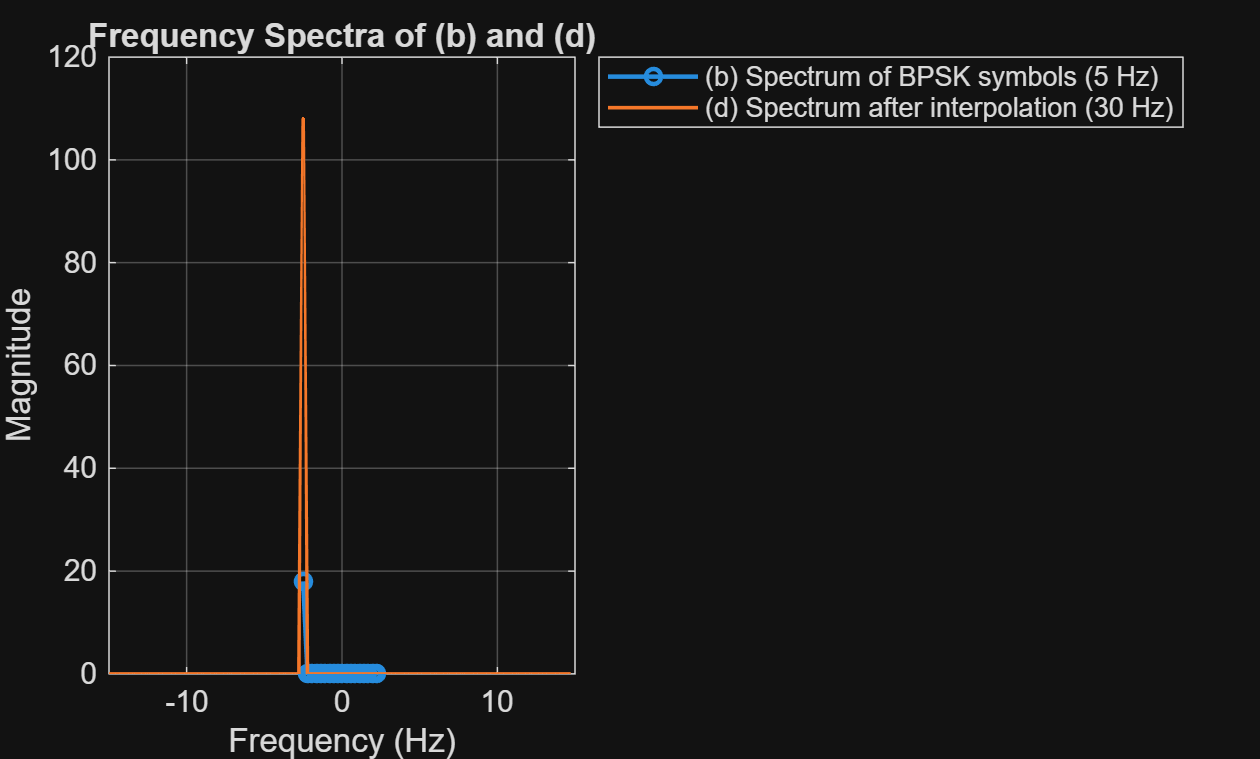

N_b   = length(Symbols);
X_b   = fftshift(fft(Symbols, N_b));
f_b   = (-N_b/2:N_b/2-1)' * (fs_sym / N_b);

N_d   = length(x_d);
f_d   = (-N_d/2:N_d/2-1)' * (fs_up / N_d);

%% Plot magnitude spectra
figure; hold on; grid on; box on;

plot(f_b, abs(X_b), 'o-', 'LineWidth', 1.5, 'MarkerSize', 5, 'DisplayName','(b) Spectrum of BPSK symbols (5 Hz)');
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.2, 'DisplayName','(d) Spectrum after interpolation (30 Hz)');

xlim([-15 15]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectra of (b) and (d)');
legend('Location','northeastoutside');

## (3) (d) and (e) in frequency domain

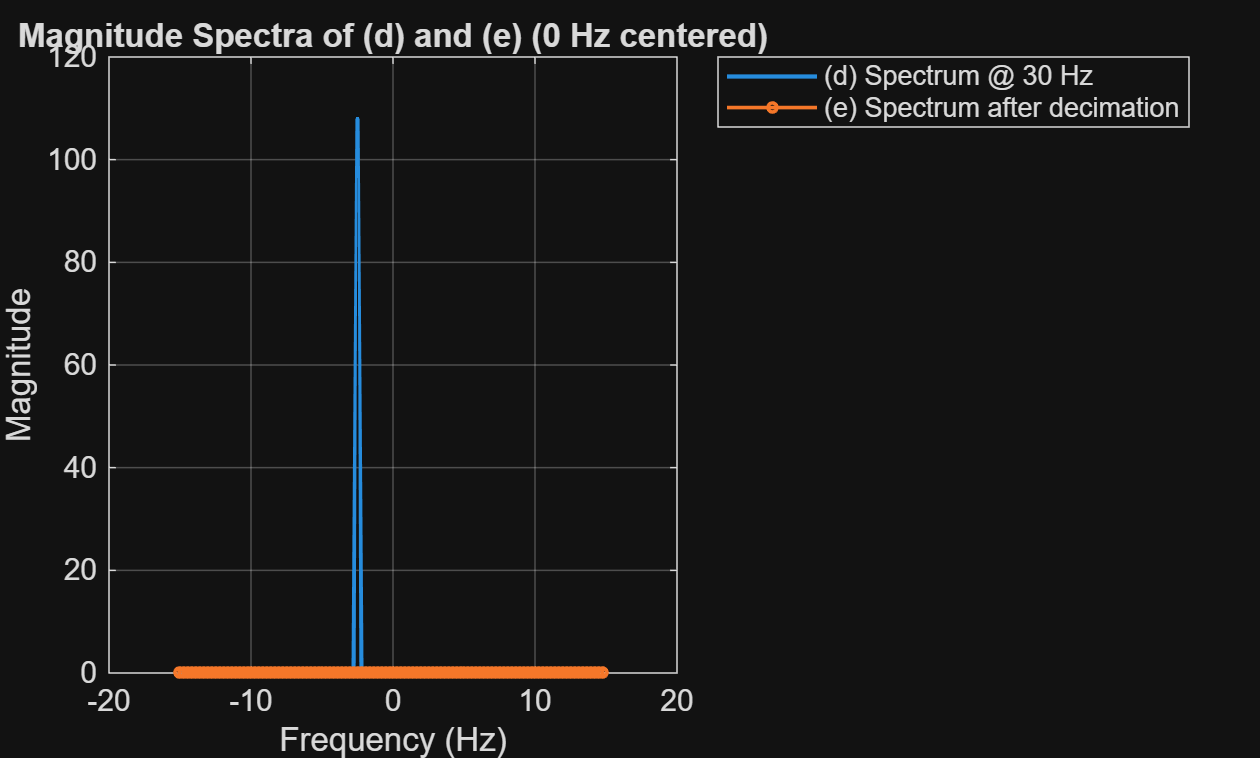

M = 9;
fs_f = fs_up/M;
f_cutoff_e = fs_f/2;

H_dec = zeros(size(f_d));
H_dec(abs(f_d)<=f_cutoff_e) = 1;

X_e = X_up_filtered.*H_dec;
N_e = length(X_e);
f_e  = (-N_e/2:N_e/2-1).'*(fs_up / N_e);

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.4, 'DisplayName', '(d) Spectrum @ 30 Hz');
plot(f_e, abs(X_e), '-o', 'LineWidth', 1.2, 'MarkerSize', 3, 'DisplayName', '(e) Spectrum after decimation');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectra of (d) and (e) (0 Hz centered)');
legend('Location','northeastoutside');

The spectrum of (e) becomes all 0 after the filter because the original spectrum of (d) is outside of the decimator filter range.

## (4) (b) (d) (f) in time domain

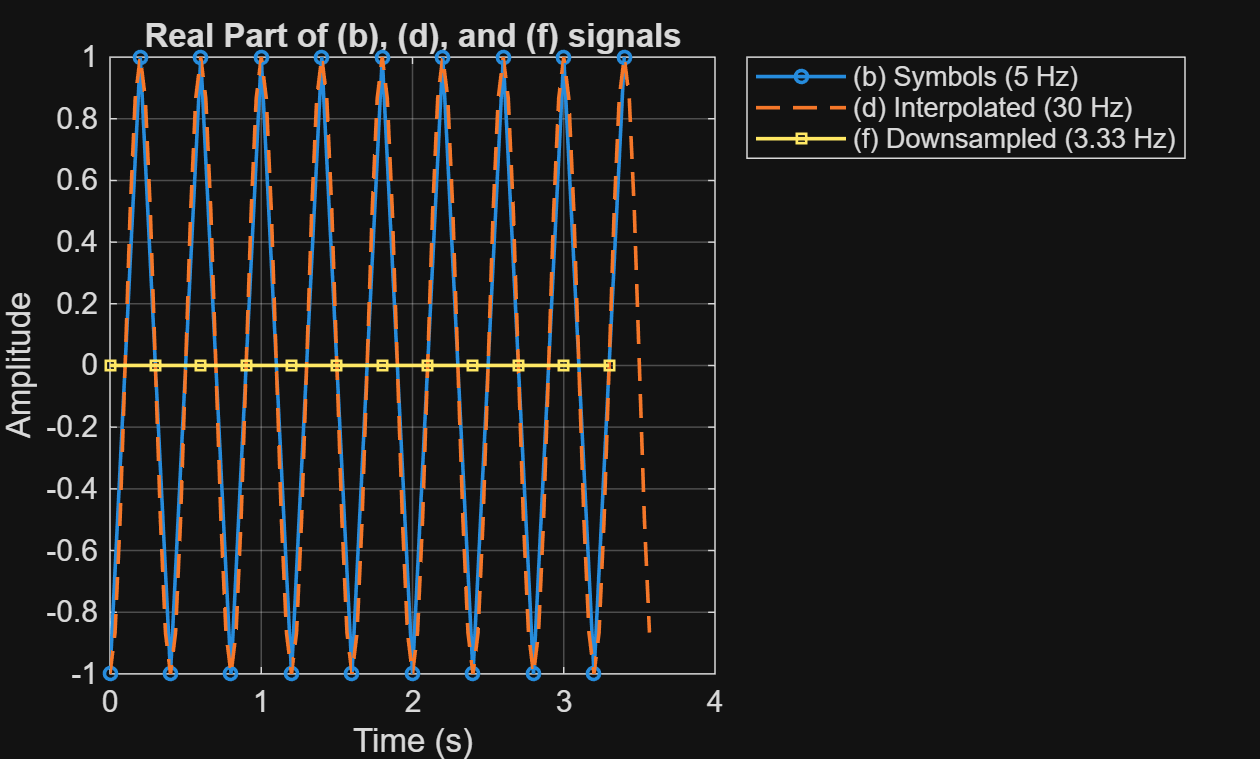

x_e = ifft(ifftshift(X_e));
x_f = x_e(1:M:end);
N_f = length(x_f);
fs_f = fs_up / M;
Tf = 1/fs_f;
t_f = t_up(1)+(0:N_f-1)'*Tf;

%% Plot real parts of (b), (d), (f)
figure; hold on; grid on; box on;
plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(b) Symbols (5 Hz)');
plot(t_up, real(x_d), '--', 'LineWidth', 1.2, 'DisplayName','(d) Interpolated (30 Hz)');
plot(t_f, real(x_f), 's-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(f) Downsampled (3.33 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b), (d), and (f) signals');
legend('Location','northeastoutside');

(f) loss all of the signal and becomes 0 at every time steps. Because the original signal carry high frequency information only, and the high frequency part is filtered out in the decimator filter.

## (5) (d) and (f) spectra with no decimator filter

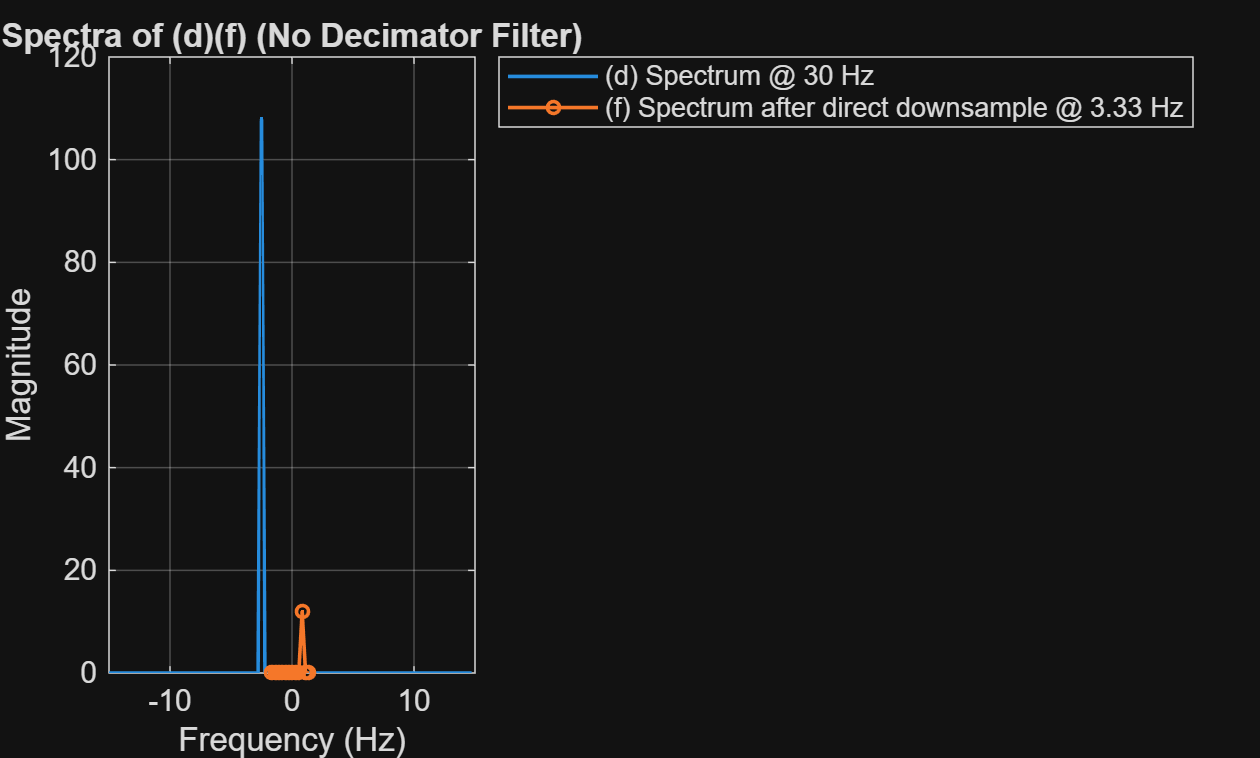

fs_d = fs_up; 
fs_f = fs_d/M; 

x_f = x_d(1:M:end);

N_f  = length(x_f);
X_f  = fftshift(fft(x_f, N_f));
f_f  = (-N_f/2:N_f/2-1).' * (fs_f / N_f);

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.2, 'DisplayName','(d) Spectrum @ 30 Hz');
plot(f_f, abs(X_f), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(f) Spectrum after direct downsample @ 3.33 Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectra of (d)(f) (No Decimator Filter)');
legend('Location','northeastoutside');
xlim([-15 15]);

There is a low frequency component in the resulting (f) spectrum instead of all zeros as in (3).

This is because that we didn't apply decimator filter. Therefore, after downsampling, the high frequency component from the replica of other periods will expand to the range of the 0Hz-centered spectrum (aliasing).

## (6) (b) (d) (f) signals with no decimator filter

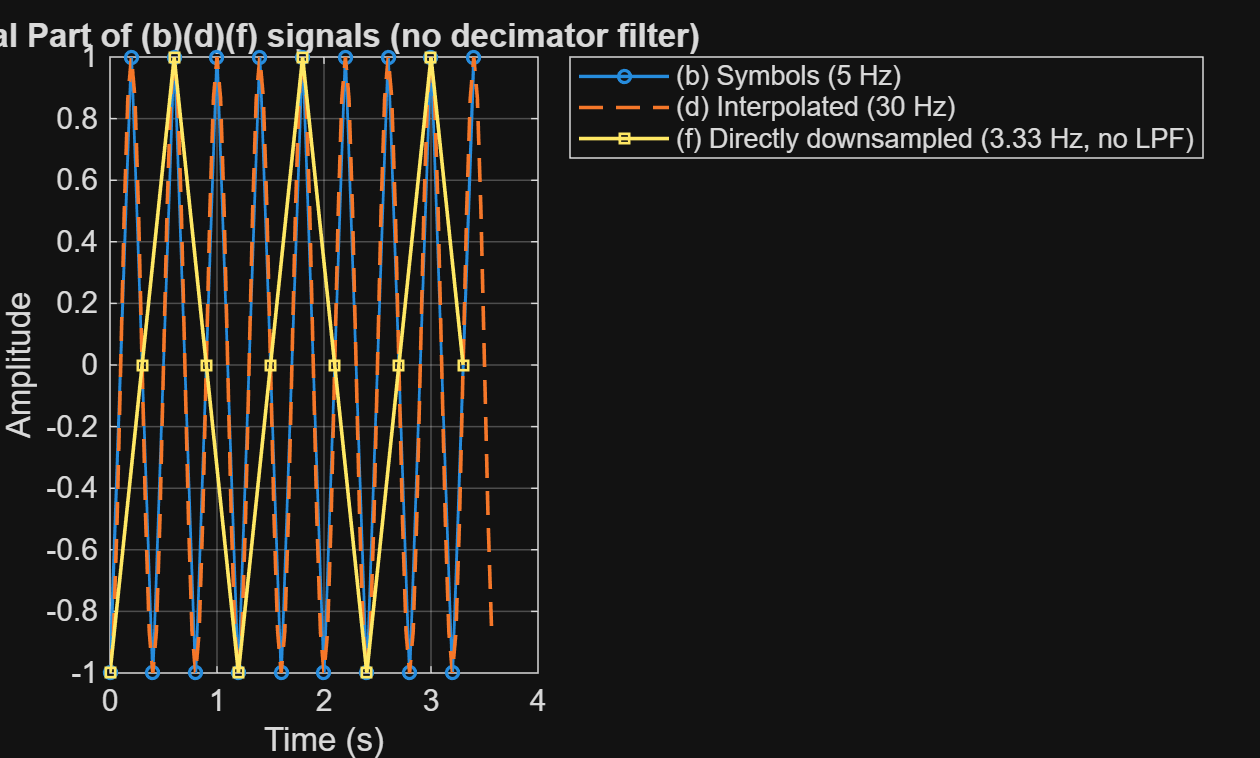

x_f_no_decimator  = x_d(1:M:end);

%% Plot real parts of (b), (d), and (f)
figure; hold on; grid on; box on;

plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols (5 Hz)');

plot(t_up, real(x_d), '--', 'LineWidth', 1.2, 'DisplayName', '(d) Interpolated (30 Hz)');

plot(t_f, real(x_f_no_decimator), 's-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', '(f) Directly downsampled (3.33 Hz, no LPF)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b)(d)(f) signals (no decimator filter)');
legend('Location','northeastoutside');

The resulting (f) is alternating in a lower frequency instead of all zeros as in (4). As stated in (5), an additional low frequency component appears due to aliasing, and thus the resulting signal contains the low frequency part.

## Bit pattern with lower frequency

## (7) (b) and (d) signals

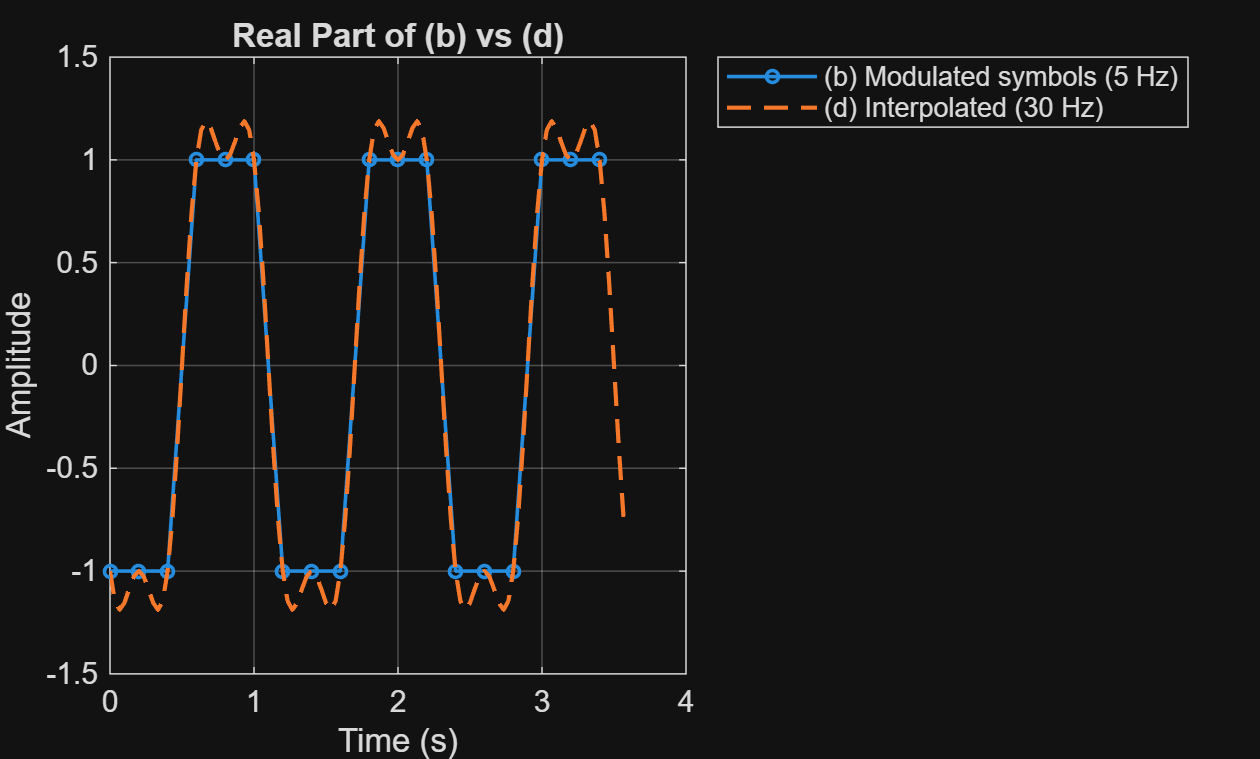

fs_sym = 5;
L      = 6;
fs_up  = fs_sym * L;

bits = [1;1;1;0;0;0;1;1;1;0;0;0;1;1;1;0;0;0];
Nsym = length(bits);

Symbols = 1-2*bits;

tSym = (0:Nsym-1)'/fs_sym;

% Upsampling
x_up = upsample(Symbols,L);
N_up = length(x_up);
t_up = (0:N_up-1)'/fs_up;

X_up = fftshift(fft(x_up,N_up));
f_up = (-N_up/2:N_up/2-1)'*(fs_up/N_up);

f_cutoff = fs_sym/2;
H  = zeros(size(f_up));
mask = (f_up < f_cutoff) & (f_up >= -f_cutoff);
H(mask) = L; 
%H(abs(f_up) <= f_cutoff) = L;

X_up_filtered = X_up .* H;
x_d = ifft(ifftshift(X_up_filtered),N_up);

%% Plot real parts of (b) and (d)
figure; hold on; grid on; box on;
plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(b) Modulated symbols (5 Hz)');
plot(t_up,  real(x_d),    '--',  'LineWidth', 1.4, 'DisplayName','(d) Interpolated (30 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b) vs (d)');
legend('Location','northeastoutside');

## (8) (b) and (d) in frequency domain

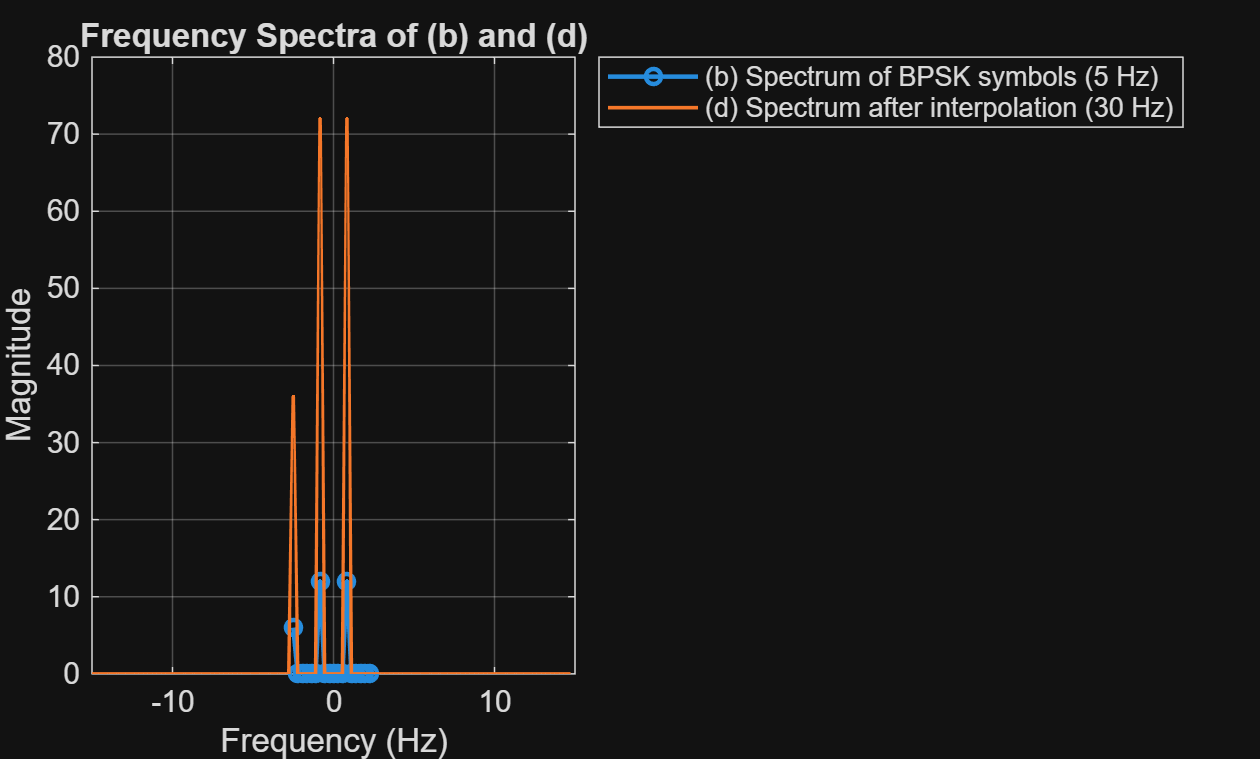

N_b   = length(Symbols);
X_b   = fftshift(fft(Symbols, N_b));
f_b   = (-N_b/2:N_b/2-1)' * (fs_sym / N_b);

N_d   = length(x_d);
f_d   = (-N_d/2:N_d/2-1)' * (fs_up / N_d);

%% Plot magnitude spectra
figure; hold on; grid on; box on;

plot(f_b, abs(X_b), 'o-', 'LineWidth', 1.5, 'MarkerSize', 5, 'DisplayName','(b) Spectrum of BPSK symbols (5 Hz)');
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.2, 'DisplayName','(d) Spectrum after interpolation (30 Hz)');

xlim([-15 15]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectra of (b) and (d)');
legend('Location','northeastoutside');

## (9) (d) and (e) in frequency domain

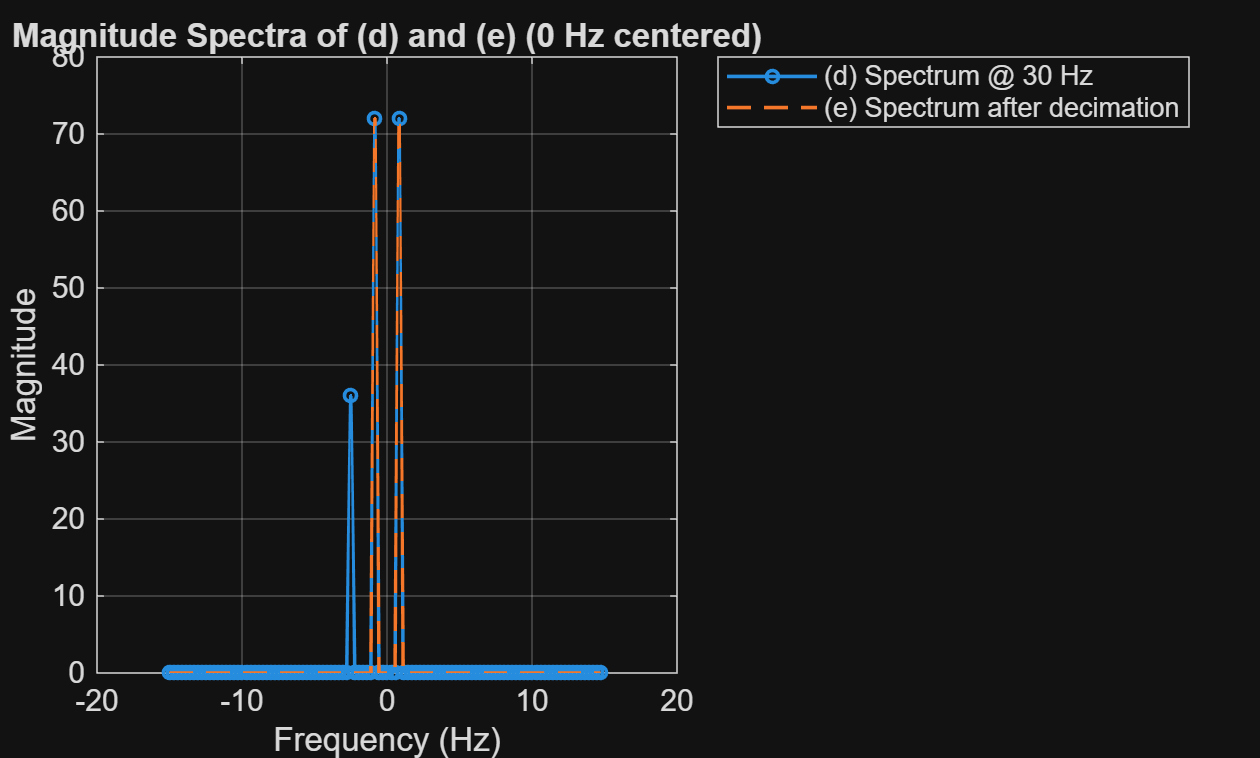

M = 9;
fs_f = fs_up/M;
f_cutoff_e = fs_f/2;

H_dec = zeros(size(f_d));
H_dec(abs(f_d)<=f_cutoff_e) = 1;

X_e = X_up_filtered.*H_dec;
N_e = length(X_e);
f_e  = (-N_e/2:N_e/2-1).'*(fs_up / N_e);

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_d, abs(X_up_filtered), '-o', 'MarkerSize', 4, 'LineWidth', 1.2, 'DisplayName', '(d) Spectrum @ 30 Hz');
plot(f_e, abs(X_e), '--', 'LineWidth', 1.2, 'DisplayName', '(e) Spectrum after decimation');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectra of (d) and (e) (0 Hz centered)');
legend('Location','northeastoutside');

A high frequency component in (d) does not appear in the spectrum of (e) because it is filtered out by the decimator filter.

## (10) (b) (d) (f) in time domain

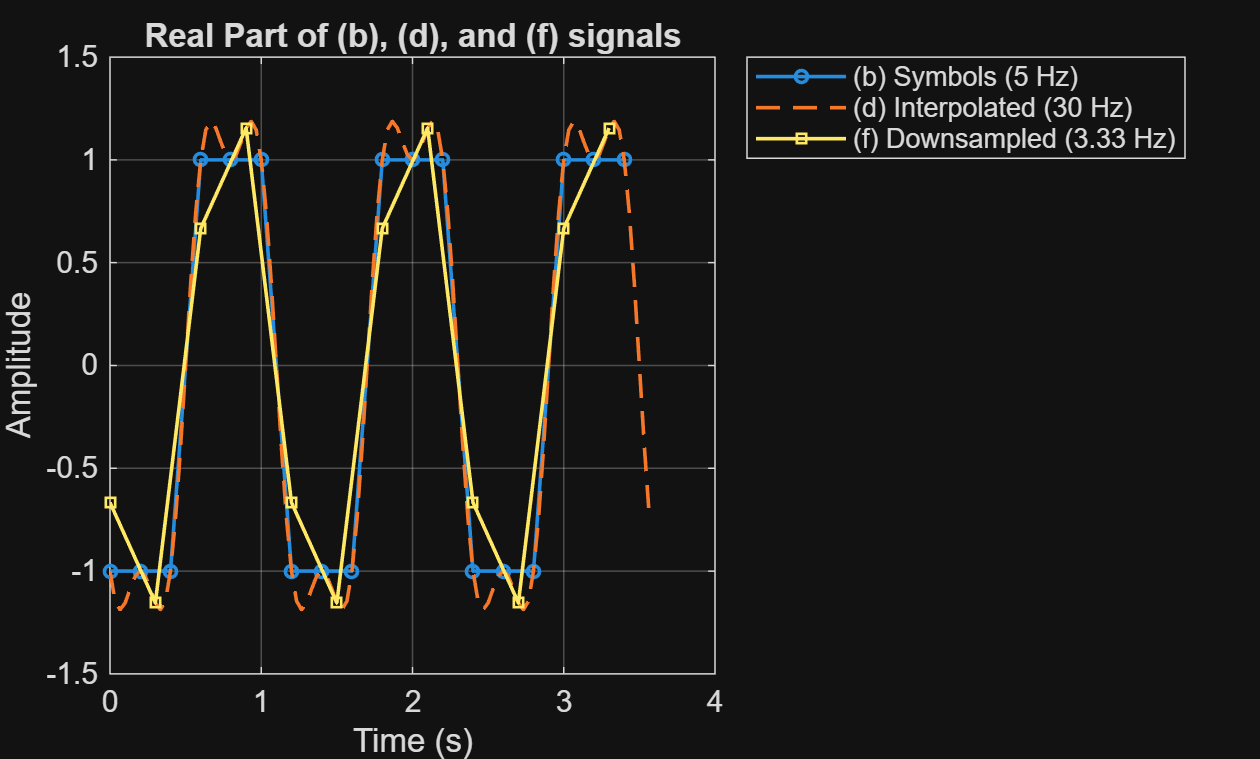

x_e = ifft(ifftshift(X_e));
x_f = x_e(1:M:end);
N_f = length(x_f);
fs_f = fs_up / M;
Tf = 1/fs_f;
t_f = t_up(1)+(0:N_f-1)'*Tf;

%% Plot real parts of (b), (d), (f)
figure; hold on; grid on; box on;
plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(b) Symbols (5 Hz)');
plot(t_up, real(x_d), '--', 'LineWidth', 1.2, 'DisplayName','(d) Interpolated (30 Hz)');
plot(t_f, real(x_f), 's-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(f) Downsampled (3.33 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b), (d), and (f) signals');
legend('Location','northeastoutside');

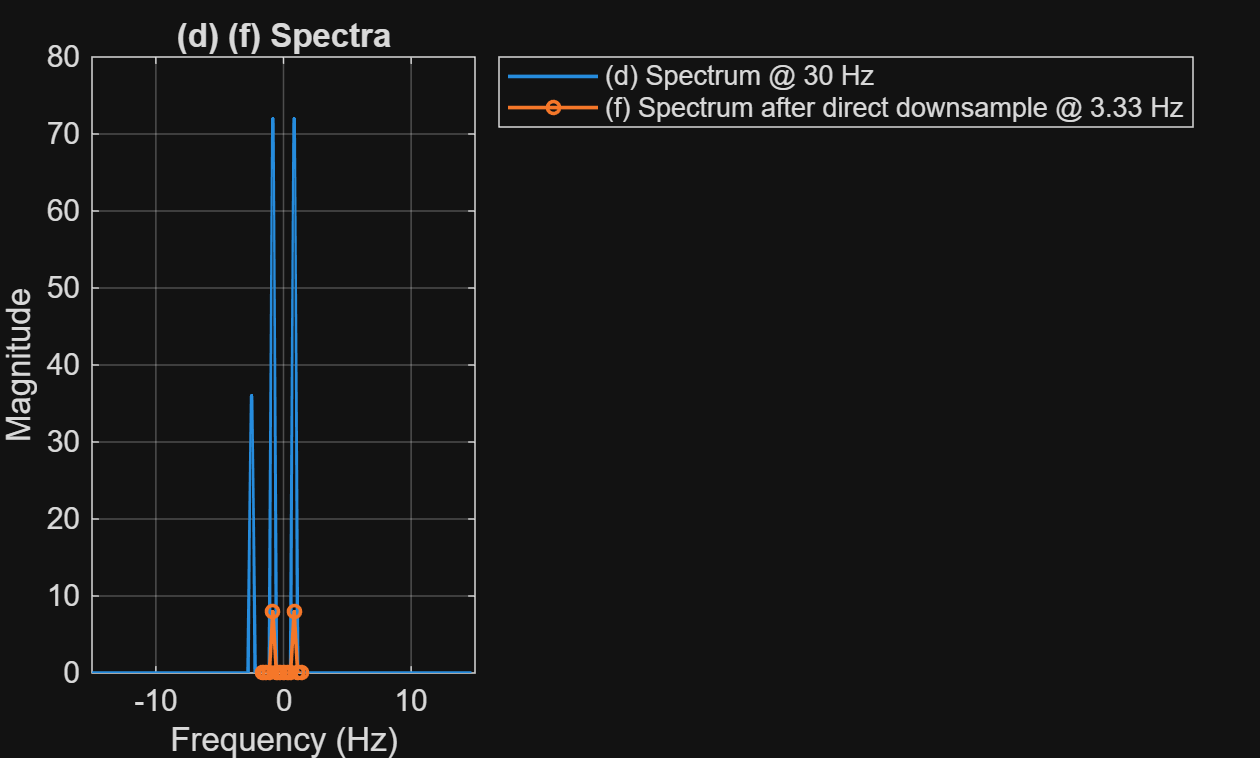

fs_d = fs_up; 
fs_f = fs_d/M; 

N_f  = length(x_f);
X_f  = fftshift(fft(x_f, N_f));
f_f  = (-N_f/2:N_f/2-1).' * (fs_f / N_f);

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.2, 'DisplayName','(d) Spectrum @ 30 Hz');
plot(f_f, abs(X_f), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(f) Spectrum after direct downsample @ 3.33 Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('(d) (f) Spectra');
legend('Location','northeastoutside');
xlim([-15 15]); 

Signal (f) doesn't align well with (b) and (d) because the high frequency component is filtered out.

## (11)  (b) (d) (f) signals with no decimator filter

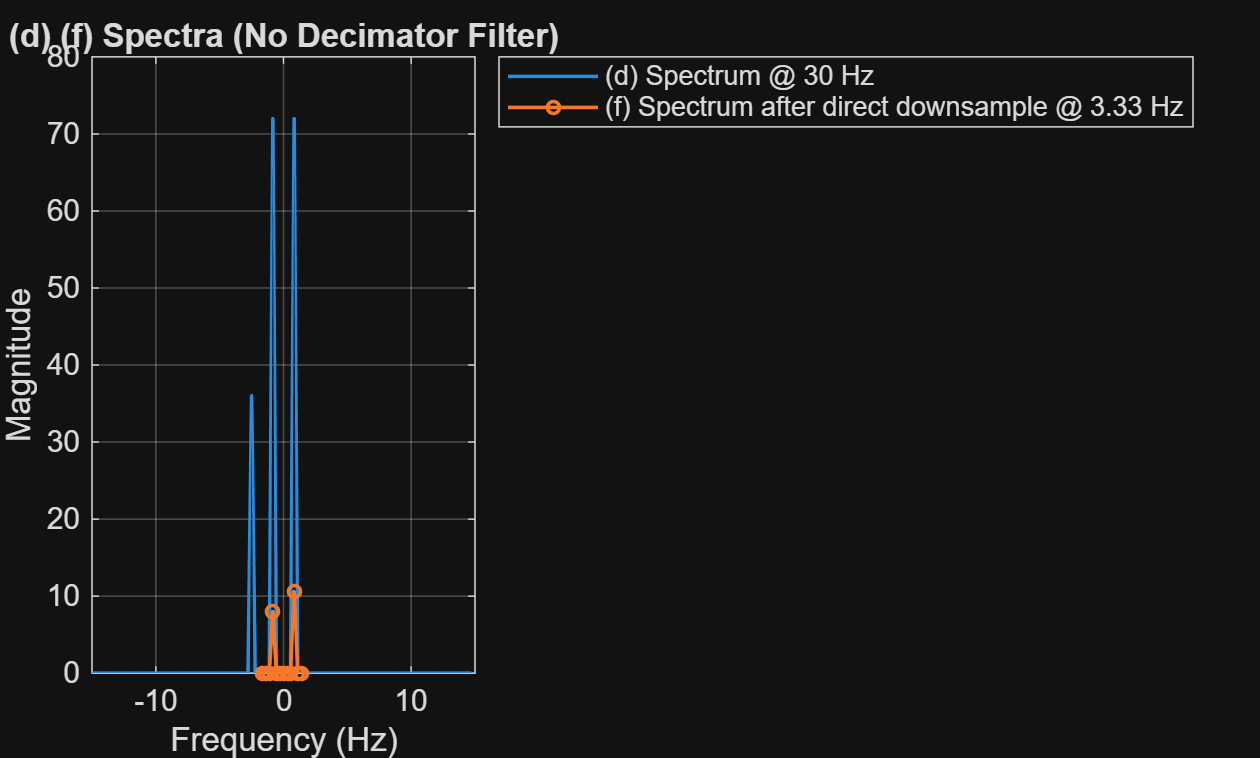

fs_d = fs_up; 
fs_f = fs_d/M; 

x_f_no_decimator = x_d(1:M:end);

N_f = length(x_f_no_decimator);
X_f = fftshift(fft(x_f_no_decimator, N_f));
f_f = (-N_f/2:N_f/2-1).' * (fs_f / N_f);

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_d, abs(X_up_filtered), '-',  'LineWidth', 1.2, 'DisplayName','(d) Spectrum @ 30 Hz');
plot(f_f, abs(X_f), 'o-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName','(f) Spectrum after direct downsample @ 3.33 Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('(d) (f) Spectra (No Decimator Filter)');
legend('Location','northeastoutside');
xlim([-15 15]); 

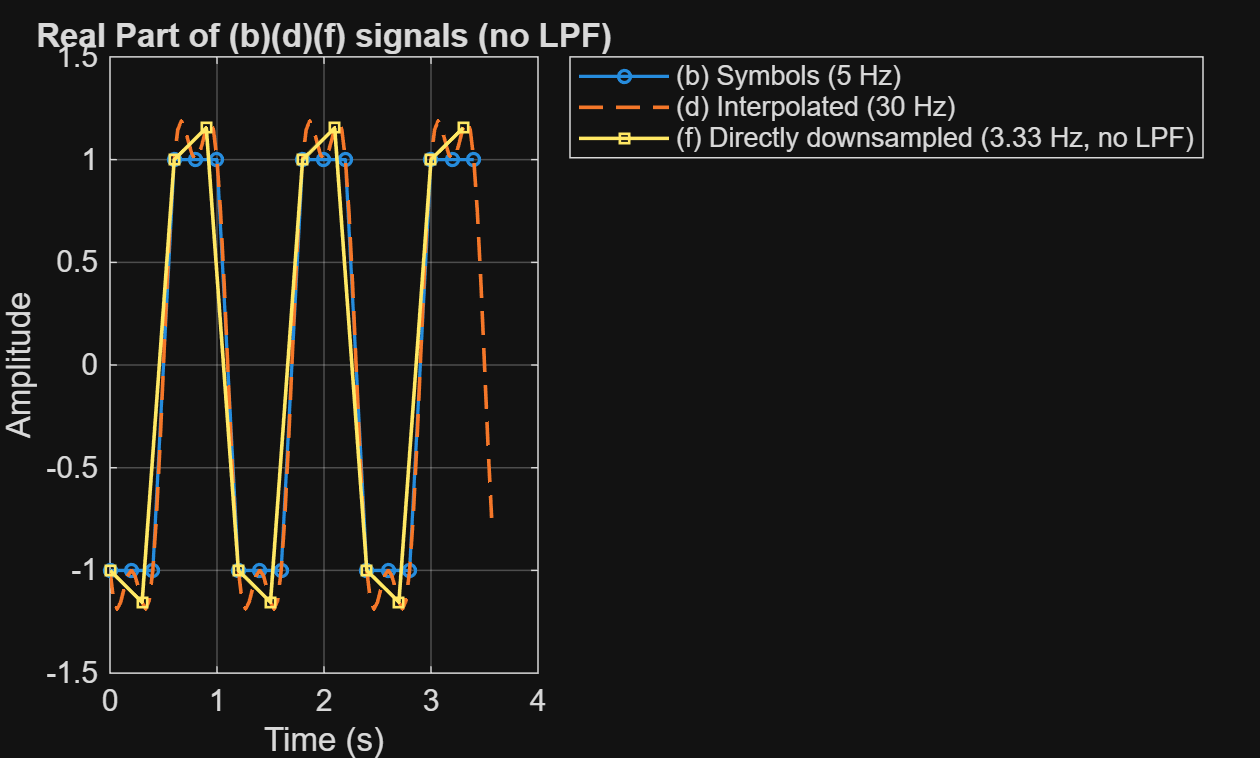


%% Plot real parts of (b), (d), and (f)
figure; hold on; grid on; box on;

plot(tSym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols (5 Hz)');
plot(t_up, real(x_d), '--', 'LineWidth', 1.2, 'DisplayName', '(d) Interpolated (30 Hz)');
plot(t_f, real(x_f_no_decimator), 's-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', '(f) Directly downsampled (3.33 Hz, no LPF)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of (b)(d)(f) signals (no LPF)');
legend('Location','northeastoutside');

The resulting (f) signal aligns better with the original signals compared to (10). This is because that the spectrum from different symbol expand to the original spectrum domain, and it accidentally compensates to the positive high frequency part and make the signal more like the original ones.

## (12) Comparison of (6) and (11)

The result in (11) better align with the original signal compared to (6), since the spectrum of the first signal concentrates all in high frequency part, the decimator filter has more effect on the reconstructed signal. In comparison, the second signal contains more low frequency part which is preserved during the filtering.

# Part 3

load("Lab2_TXSig.mat");

## (1) RRC filters for tx and rx

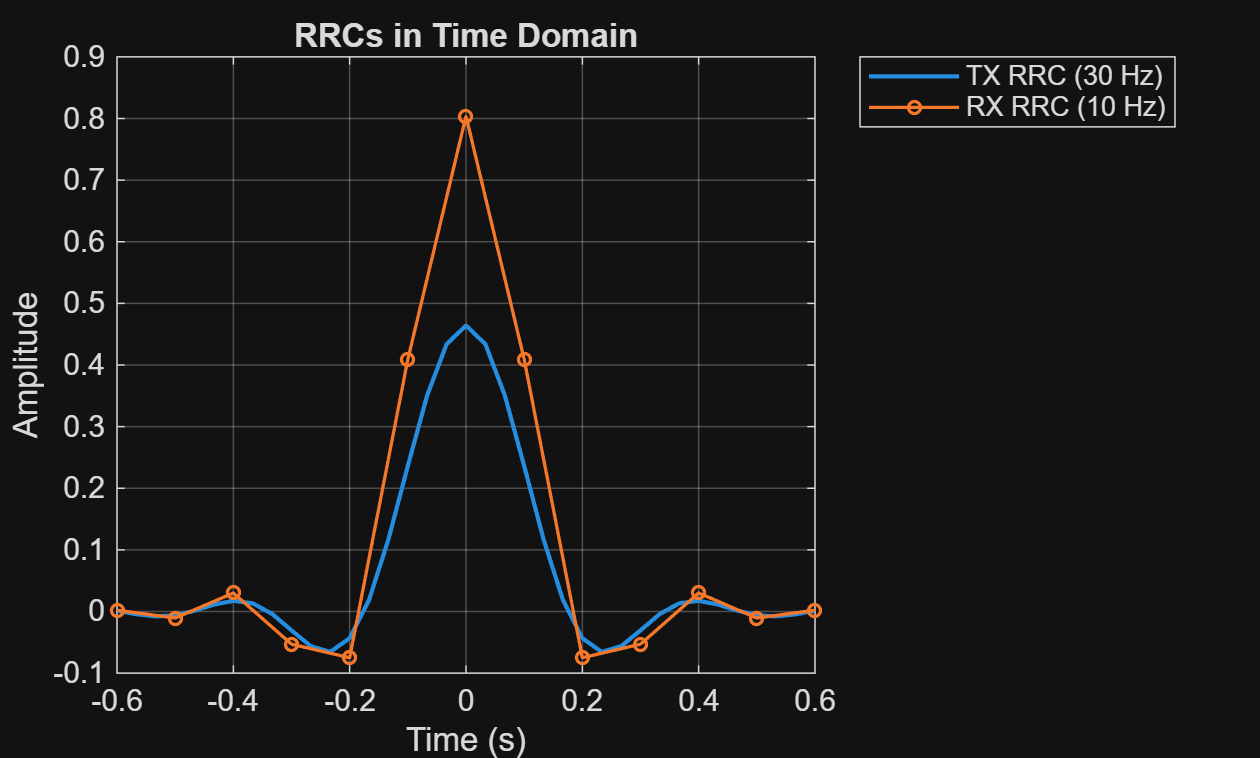

fs_sym = 5;      
Ts = 1/fs_sym;  
alpha = 0.5;   
span = 6;  

fs_TX = 30; 
fs_RX = 10;

%samples per symbol
sps_tx = fs_TX / fs_sym;  
sps_rx = fs_RX / fs_sym; 

h_tx = rcosdesign(alpha, span, sps_tx, 'sqrt');
h_rx = rcosdesign(alpha, span, sps_rx, 'sqrt'); 

t_tx = (-span/2 : 1/sps_tx : span/2) * Ts;   
t_rx = (-span/2 : 1/sps_rx : span/2) * Ts;  

%% Plot both in time domain
figure; hold on; grid on; box on;
plot(t_tx, h_tx, '-', 'LineWidth', 1.4, 'DisplayName', 'TX RRC (30 Hz)');
plot(t_rx, h_rx, 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', 'RX RRC (10 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('RRCs in Time Domain');
legend('Location','northeastoutside');

## (2) RRC filters in frequency domain

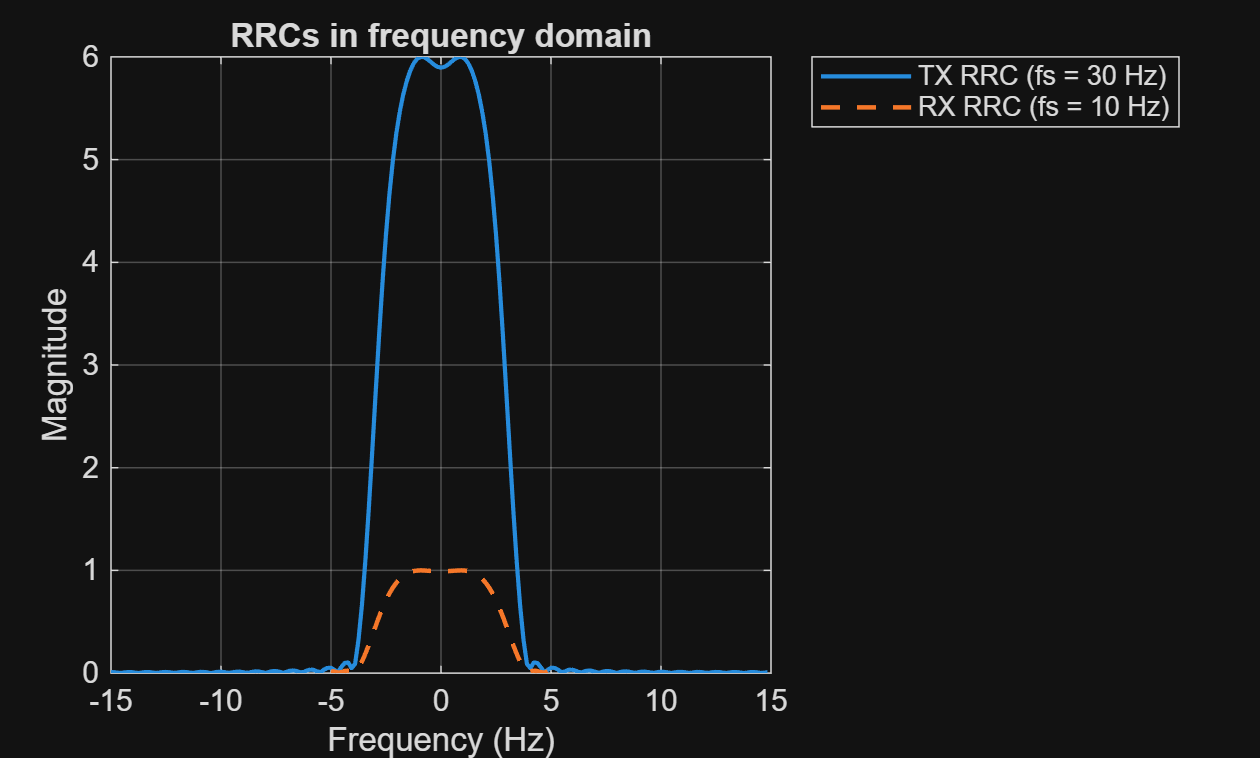

L = fs_TX/fs_sym;
x_up = upsample(Symbols, L); 
filter_tx_max = L;
filter_rx_max = 1;
%N_tx = length(h_tx);
N_tx = length(x_up);
%N_rx = length(h_rx);
N_rx = length(x_up)/3;
H_tx = fftshift(fft(h_tx, N_tx));
f_tx = (-N_tx/2:N_tx/2-1) * (fs_TX / N_tx);

H_rx = fftshift(fft(h_rx, N_rx));
f_rx = (-N_rx/2:N_rx/2-1) * (fs_RX / N_rx);

H_tx = H_tx * (filter_tx_max / max(abs(H_tx)));
H_rx = H_rx * (filter_rx_max / max(abs(H_rx)));

%% Plot magnitude spectra
figure; hold on; grid on; box on;
plot(f_tx, abs(H_tx), '-', 'LineWidth', 1.4, 'DisplayName', 'TX RRC (fs = 30 Hz)');
plot(f_rx, abs(H_rx), '--', 'LineWidth', 1.5, 'DisplayName', 'RX RRC (fs = 10 Hz)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('RRCs in frequency domain');
legend('Location','northeastoutside');
xlim([-15 15]);

## (3) RRC to (c) and obtain (d)

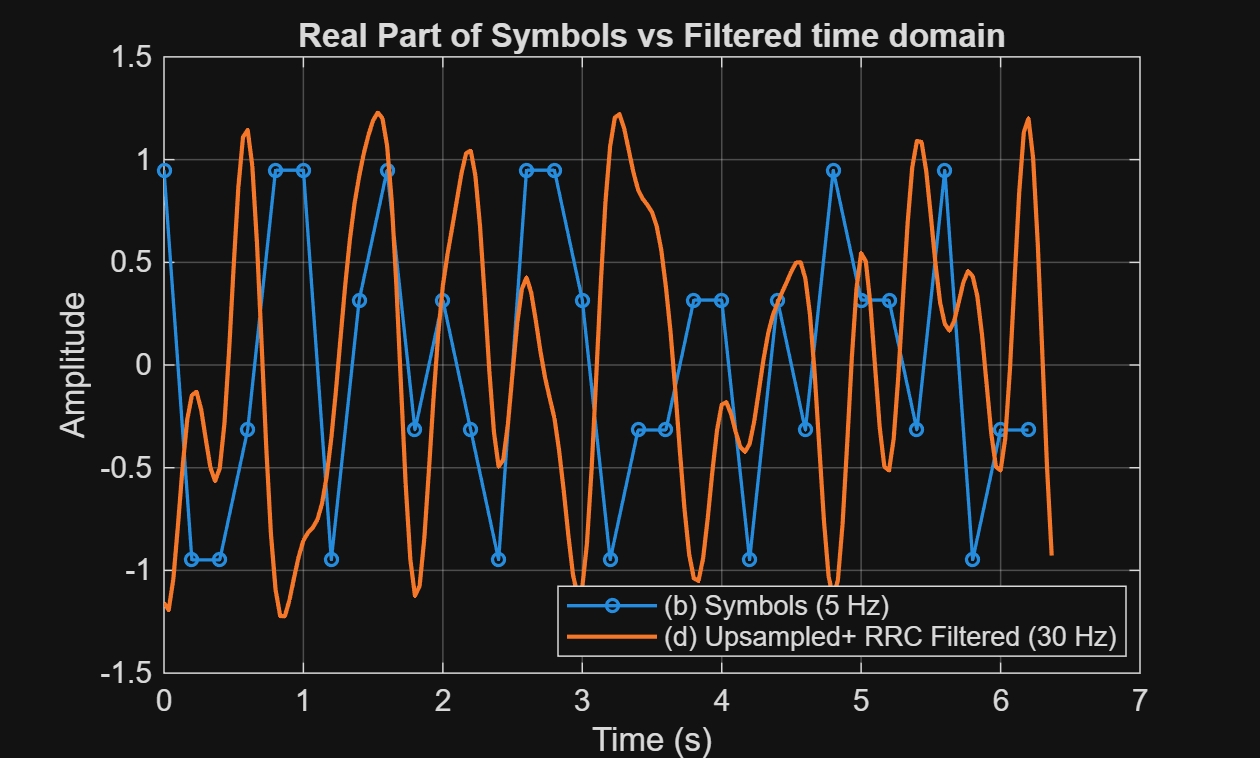

L = fs_TX/fs_sym;
Tdac = 1/fs_TX;   

t_Sym = tSamp(:);

%Upsampling
x_up = upsample(Symbols, L); 
Nup  = length(x_up);
t_up = t_Sym(1) + (0:Nup-1).' * Tdac;

X_up = fftshift(fft(x_up));
X_up_RRCed = X_up .* H_tx.';

x_up_RRCed = ifft(ifftshift(X_up_RRCed));


%% Plot real parts of (b) and (d)
figure; hold on; grid on; box on;

%(b)
plot(t_Sym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols (5 Hz)');
%(d)
plot(t_up, real(x_up_RRCed), '-', 'LineWidth', 1.4, 'DisplayName', '(d) Upsampled+ RRC Filtered (30 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('Real Part of Symbols vs Filtered time domain');
legend('Location','best');

## Yes, inter symbol interference is observed

Some transmitted signals are almost at the opposite side of the original symbol.

## (4) Time domain Signal of (b) (d) (f)

M_de = fs_TX/fs_RX;
x_e  = x_up_RRCed(1:M_de:end);
t_e  = t_up(1:M_de:end); 
X_e = fftshift(fft(x_e));
X_e_RRCed = X_e .* H_rx.';
x_f = ifft(ifftshift(X_e_RRCed));
t_f = t_e;

figure; hold on; grid on; box on;
plot(t_Sym, real(Symbols), 'o-', 'LineWidth', 1.1, 'MarkerSize', 4, 'DisplayName', '(b) Symbols (real, 5 Hz)');
plot(t_up, real(x_up_RRCed), '-', 'LineWidth', 1.2, 'DisplayName', '(d) TX RRC output (real, 30 Hz)');
plot(t_f, real(x_f), '-', 'LineWidth', 1.4, 'DisplayName', '(f) After RX RRC (real, 10 Hz)');

xlabel('Time (s)');
ylabel('Amplitude');
title('(b)(d)(f) Signals with RRC Filtering');
legend('Location','best');

Yes inter symbol interference is observed. The inter-symbol interference will only disappear after we downsample to the original frequency where signals from other symbols will disappear at the sampling time point. 

## (5) Signal reconstruction and BER

x_downsampled = x_f(1:2:end);
est_bits = qamdemod(x_downsampled, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');

figure; hold on; grid on; box on; axis equal;
plot(real(Symbols), imag(Symbols), 'o', 'MarkerSize', 5, 'DisplayName', 'TX constellation');
plot(real(x_downsampled),    imag(x_downsampled),    '.', 'MarkerSize', 10, 'DisplayName', 'RX constellation (after RRC & downsample)');
xlabel('In-Phase (I)'); ylabel('Quadrature (Q)');
title('Transmit vs. Received Constellations');
legend('Location','northeastoutside');

Yes, they are identical!!!!! (The received symbols are a little bit away from the original point but still very close)